
t = 0:0.001:5;
alpha = 1;
Fs = 44100 %sample frequency

Fs = 44100

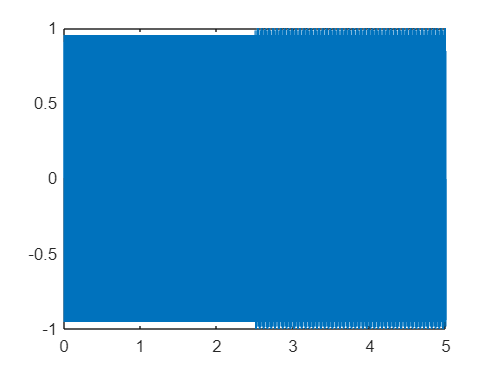

f1 = sin(2*200*pi*alpha*t);
f2 = sin(2*220*pi*alpha*t);
resultant = [f1(1:2500) f2(2501:5001)];
resultant = resultant/max(abs(resultant));
plot(t,resultant);

filename = 'resultant.wav';

audiowrite(filename,resultant,Fs);
sound(resultant,Fs);